最大裕度的C2设计


$$P=\frac{s^4 +3s^3 +3s^2 +5s+4}{{2s}^3 +2s^2 +3s+1}$$


clear
denum = [1 3 3 5 4]; 
num = [2 2  3 1];    
Plant = tf(num,denum);
Q2=TwoDOFFeedbackTuningFunction(num,denum);

谱分解无明显误差


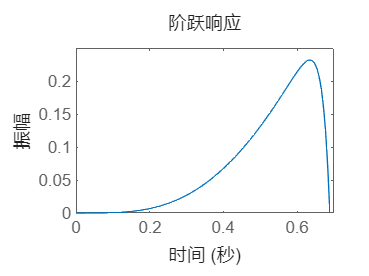

[Q1,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = (Plant*C1)/(1+Plant*C2);
step(T)

老师C2设计

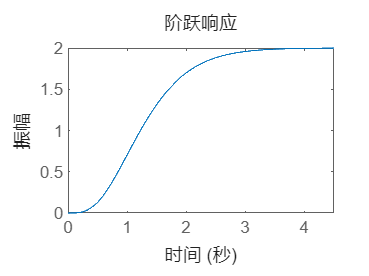

clear
denum = [1 3 3 5 4]; 
num = [2 2 3 1];  
Plant = tf(num,denum);
Q2 = opt_poly(Plant);
[Q1,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = (Plant*C1)/(1+Plant*C2);
step(T)